clear
p = [1 3 0 4]; %p(s) = s^3 + 3s^2 + 4
r = roots(p)   %求解方程的根

r =   -3.3553 + 0.0000i
   0.1777 + 1.0773i
   0.1777 - 1.0773i


p = poly(r)   %根据根重构多项式

p =     1.0000    3.0000   -0.0000    4.0000


clear
p = [3,2,1];
q = [1,4];
n = conv(p,q)   %conv()函数计算多项式的乘积

n =      3    14     9     4


value = polyval(n,-5)  %polyval()函数计算多项式中变量取具体值时的结果

value = -66

clear
num1 = [10];
den1 = [1 2 5];
sys1 = tf(num1,den1)   %tf()函数传递函数 = num/den

sys1 =
 
       10
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



num2 = [1];
den2 = [1 1];
sys2 = tf(num2,den2)

sys2 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



sys = sys1 + sys2

sys =
 
     s^2 + 12 s + 15
  ---------------------
  s^3 + 3 s^2 + 7 s + 5
 
Continuous-time transfer function.



clear
sys = tf([1 10],[1 2 1])

sys =
 
     s + 10
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



p = pole(sys)   %系统极点

p =     -1
    -1


z = zero(sys)   %系统零点

z = -10

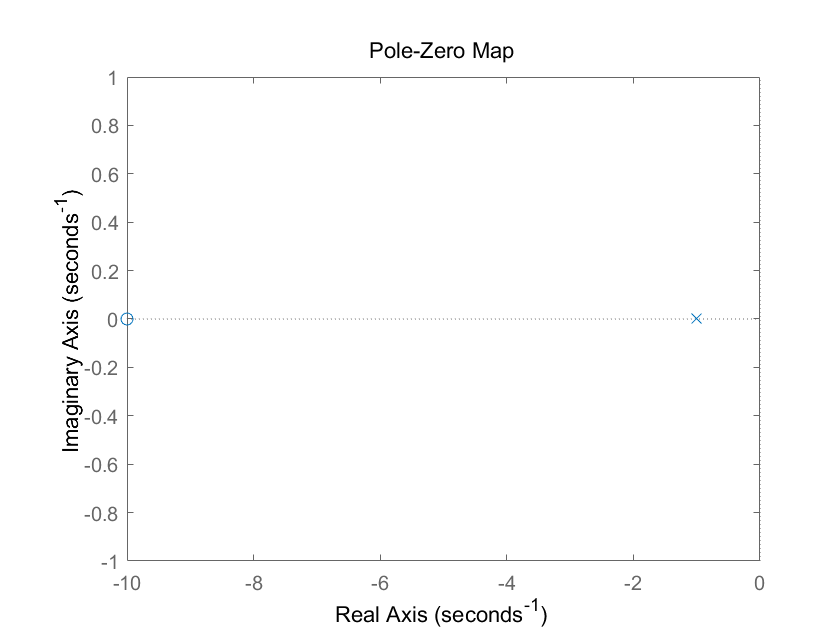

pzmap(sys)

[~,~] = pzmap(sys)


clear
sys = tf([6 0 1],[1 3 3 1])

sys =
 
        6 s^2 + 1
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.



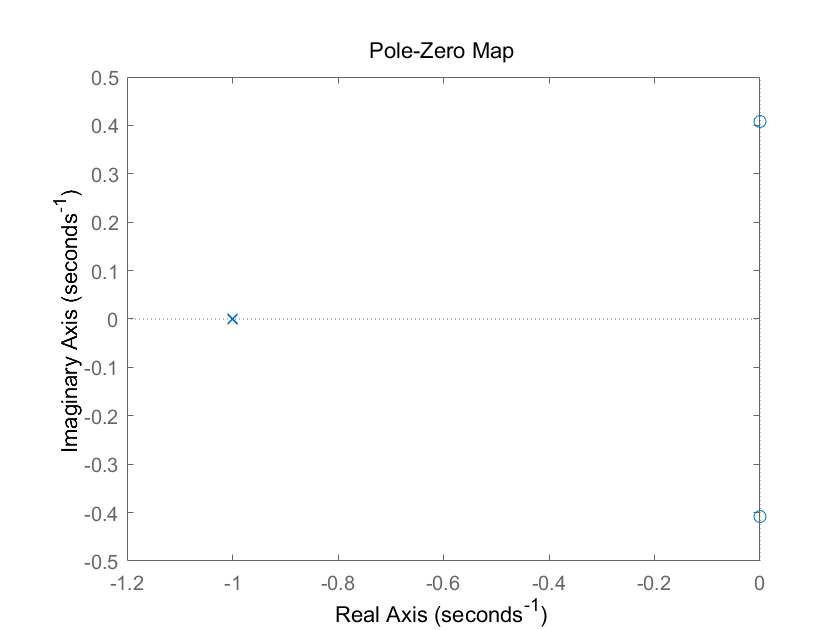

pzmap(sys)

[~,~] = pzmap(sys)

clear
sys = tf(conv([1 1],[1 2]),conv(conv([1 2i],[1 -2i]),[1 3]))

sys =
 
      s^2 + 3 s + 2
  ----------------------
  s^3 + 3 s^2 + 4 s + 12
 
Continuous-time transfer function.



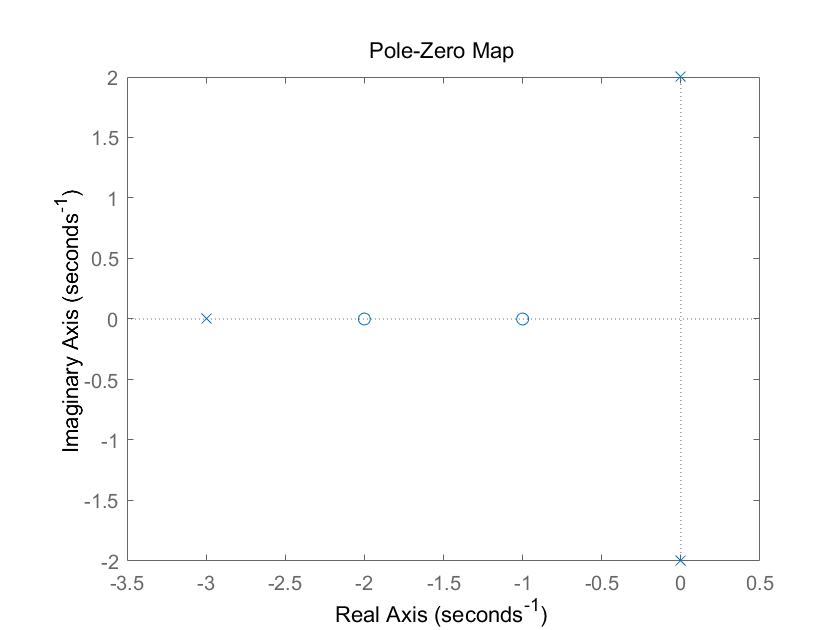

pzmap(sys)

[~,~] = pzmap(sys)

clear
G = tf([6 0 1],[1 3 3 1]);
H = tf(conv([1 1],[1 2]),conv(conv([1 2i],[1 -2i]),[1 3]));
sys = G / H

sys =
 
  6 s^5 + 18 s^4 + 25 s^3 + 75 s^2 + 4 s + 12
  -------------------------------------------
    s^5 + 6 s^4 + 14 s^3 + 16 s^2 + 9 s + 2
 
Continuous-time transfer function.



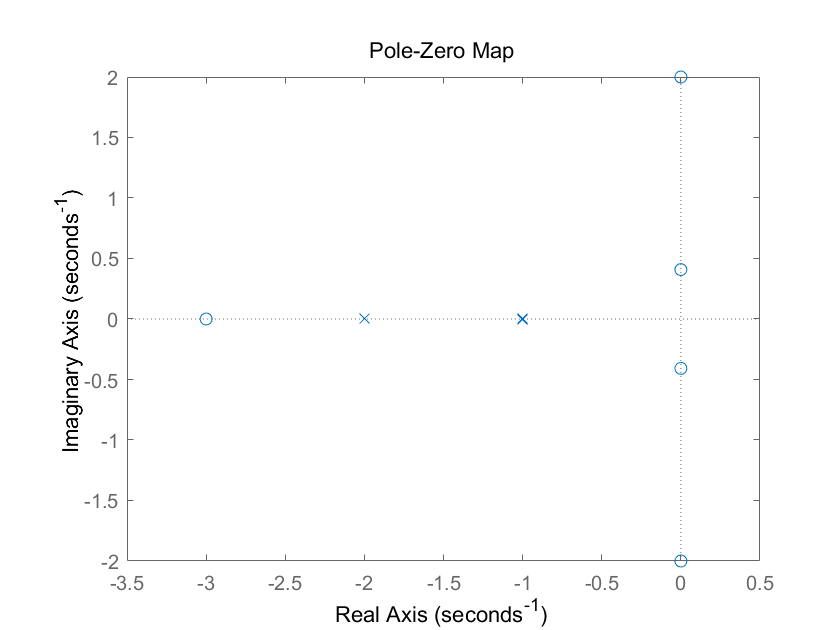

pzmap(sys)

[P,Z] = pzmap(sys)

P =   -2.0000 + 0.0000i
  -1.0002 + 0.0002i
  -1.0002 - 0.0002i
  -0.9998 + 0.0002i
  -0.9998 - 0.0002i


Z =   -3.0000 + 0.0000i
  -0.0000 + 2.0000i
  -0.0000 - 2.0000i
   0.0000 + 0.4082i
   0.0000 - 0.4082i


clear
Gc = tf([1 1],[1 2]);
G = tf([1],[500 0 0])

G =
 
     1
  -------
  500 s^2
 
Continuous-time transfer function.



sys = Gc*G;
sys1 = series(G,Gc)

sys1 =
 
        s + 1
  ------------------
  500 s^3 + 1000 s^2
 
Continuous-time transfer function.



H = [1];    %反馈函数H(s) 若为单位负反馈H则为1，sign为-1(默认值);
sign = -1;
[sys] = feedback(sys1,H,sign)

sys =
 
            s + 1
  --------------------------
  500 s^3 + 1000 s^2 + s + 1
 
Continuous-time transfer function.



clear
Gc = tf([1 1],[1 2]);
G = tf([1],[500 0 0]);
sys1 = Gc*G;
H = [1];
sys = feedback(sys1,H,-1)

sys =
 
            s + 1
  --------------------------
  500 s^3 + 1000 s^2 + s + 1
 
Continuous-time transfer function.



clear
G = tf([1],[500 0 0]);
H = tf([1 1],[1 2]);
sys = feedback(G,H,-1)

sys =
 
            s + 2
  --------------------------
  500 s^3 + 1000 s^2 + s + 1
 
Continuous-time transfer function.



minreal(G/(1+G*H))

ans =
 
         0.002 s + 0.004
  -----------------------------
  s^3 + 2 s^2 + 0.002 s + 0.002
 
Continuous-time transfer function.



parallel(G,H)   %传递函数加法

ans =
 
  500 s^3 + 500 s^2 + s + 2
  -------------------------
     500 s^3 + 1000 s^2
 
Continuous-time transfer function.



G+H

ans =
 
  500 s^3 + 500 s^2 + s + 2
  -------------------------
     500 s^3 + 1000 s^2
 
Continuous-time transfer function.

